clc
clear
close all

## 问题1

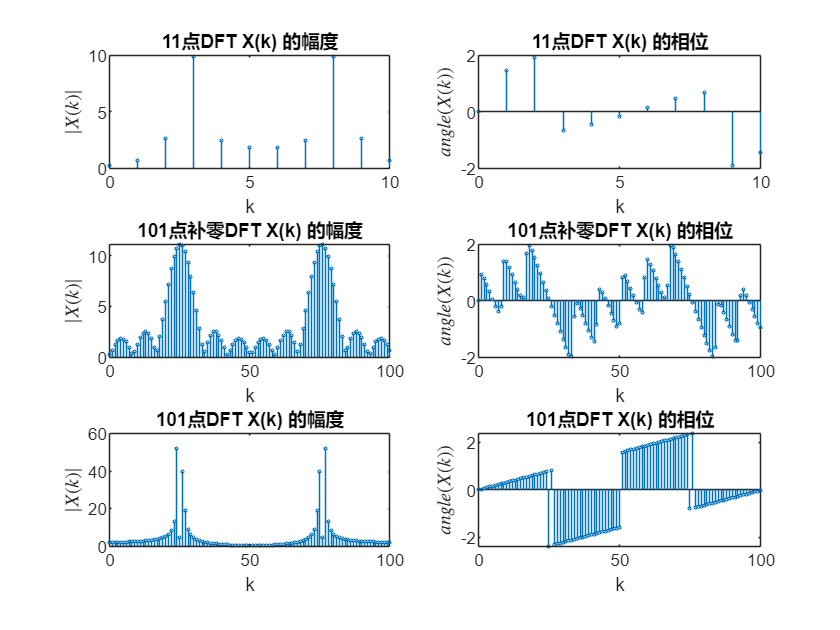

%生成数据
% 11点DFT
n = 0:1:10;
xn =  cos(0.48*pi*n) + cos(0.52*pi*n);
[Xk11,k11]= dft(xn,length(xn));

% 补90个0
xn = [xn,zeros(1,90)];
[Xk90,k90] = dft(xn,length(xn));

% 高分辨率
n = 0:1:100;
xn =  cos(0.48*pi*n) + cos(0.52*pi*n);
[Xk101,k101] = dft(xn,length(xn));

% 11点DFT
figure
subplot(3,2,1)
stem(k11,abs(Xk11),MarkerSize=1.5)
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
title("11点DFT X(k) 的幅度")
subplot(3,2,2)
stem(k11,angle(Xk11),MarkerSize=1.5)
title('11点DFT X(k) 的相位')
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")
% 补90个0
subplot(3,2,3)
stem(k90,abs(Xk90),MarkerSize=1.5)
title("101点补零DFT X(k) 的幅度")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,4)
stem(k90,angle(Xk90),MarkerSize=1.5)
title('101点补零DFT X(k) 的相位')
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")
% 高分辨率
subplot(3,2,5)
stem(k101,abs(Xk101),MarkerSize=1.5)
title("101点DFT X(k) 的幅度")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,6)
stem(k101,angle(Xk101),MarkerSize=1.5)
title('101点DFT X(k) 的相位')
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

## 问题2

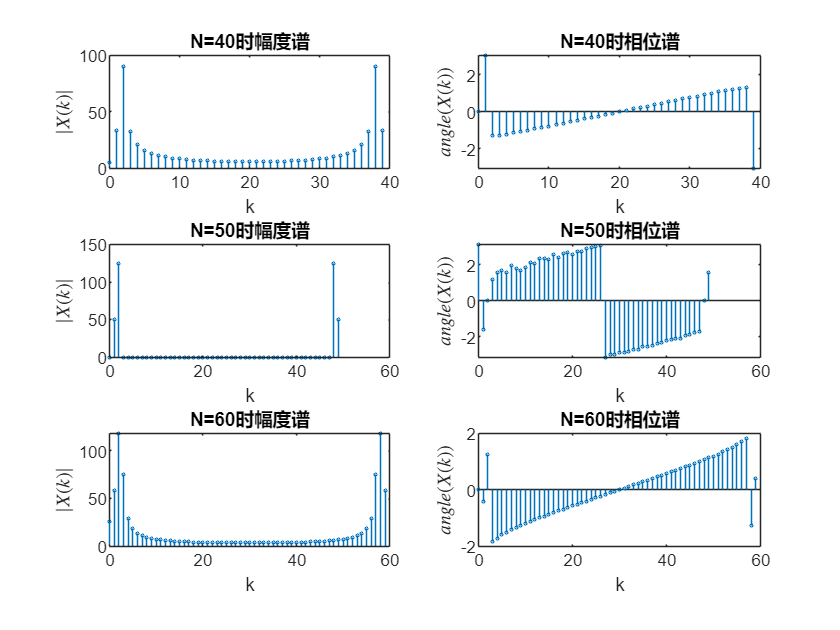

% 问题（2）
n = 40;
ts = 0.01;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk1,k1] = dft(xn,length(xn));
n = 50;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk2,k2] = dft(xn,length(xn));
n = 60;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk3,k3] = dft(xn,length(xn));

figure
subplot(3,2,1)
stem(k1,abs(Xk1),MarkerSize=1.5)
title("N=40时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,2)
stem(k1,angle(Xk1),MarkerSize=1.5)
title("N=40时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

subplot(3,2,3)
stem(k2,abs(Xk2),MarkerSize=1.5)
title("N=50时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,4)
stem(k2,angle(Xk2),MarkerSize=1.5)
title("N=50时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

subplot(3,2,5)
stem(k3,abs(Xk3),MarkerSize=1.5)
title("N=60时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,6)
stem(k3,angle(Xk3),MarkerSize=1.5)
title("N=60时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

最佳N值为N=50

问题1最佳N值选择：

对于 xa(t) = 2*sin(4*pi*t) + 5*cos(8*pi*t)，频率分量为 f1 = 2 Hz 和 f2 = 4 Hz。

抽样频率为 fs = 1/Ts = 100 Hz，频率分辨率为 Δf = fs / N。

为精确估计信号幅度谱，需要 Δf 刚好能够分割 f1 和 f2。

计算各N值的Δf：

N = 40: Δf = 100 / 40 = 2.5 Hz，f1 = 2 Hz 无法准确对齐。

N = 50: Δf = 100 / 50 = 2.0 Hz，f1 = 2 Hz 和 f2 = 4 Hz 能精确对齐。

N = 60: Δf = 100 / 60 ≈ 1.67 Hz，虽然分辨率更高，但增加了不必要的计算复杂度。

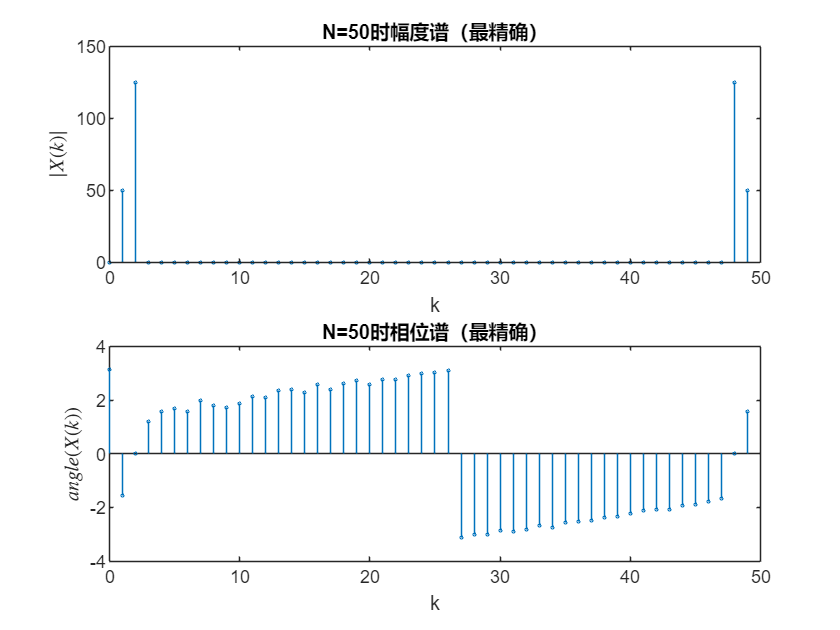

figure
subplot(2,1,1)
stem(k2,abs(Xk2),MarkerSize=1.5)
title("N=50时幅度谱（最精确）")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(2,1,2)
stem(k2,angle(Xk2),MarkerSize=1.5)
title("N=50时相位谱（最精确）")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

问题2幅度谱泄漏量最小的 N 值选择：

对于 xa(t) = 2*sin(4*pi*t) + 5*cos(8*pi*t)，频率分量为 f1 = 2 Hz 和 f2 = 4 Hz。

为最小化幅度谱泄漏量，需要较高的频率分辨率 Δf = fs / N，且频率分量尽可能对齐离散频谱采样点。

计算各N值的Δf：

N = 90: Δf = 100 / 90 ≈ 1.11 Hz，f1 和 f2 无法精确对齐。

N = 95: Δf = 100 / 95 ≈ 1.05 Hz，f1 和 f2 无法精确对齐。

N = 99: Δf = 100 / 99 ≈ 1.01 Hz，f1 = 2 Hz 和 f2 = 4 Hz 几乎完全对齐。

所以N=99幅度谱泄漏量最小

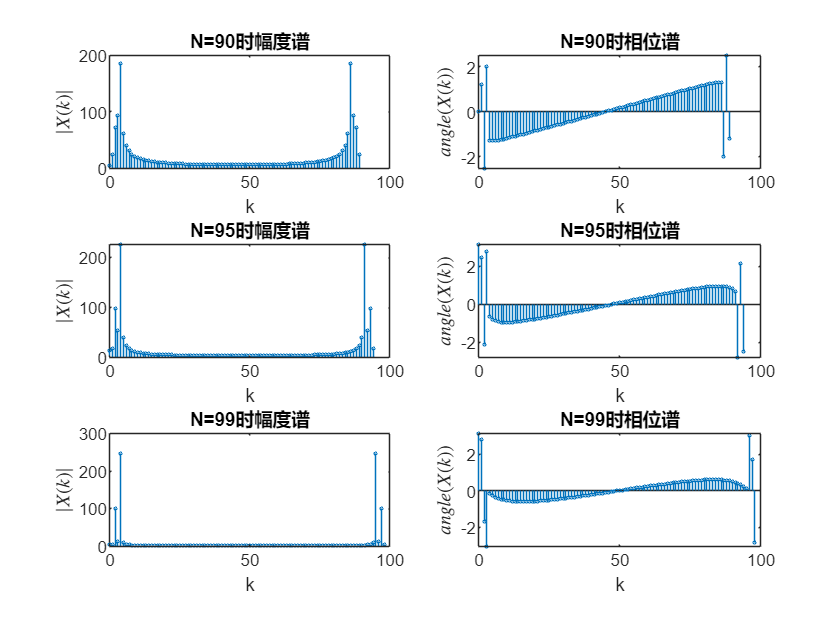

n = 90;
ts = 0.01;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk1,k1] = dft(xn,length(xn));
n = 95;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk2,k2] = dft(xn,length(xn));
n = 99;
t = 0:ts:(n-1)*ts;
xn = 2*sin(4*pi*t)+5*cos(8*pi*t);
[Xk3,k3] = dft(xn,length(xn));

figure
subplot(3,2,1)
stem(k1,abs(Xk1),MarkerSize=1.5)
title("N=90时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,2)
stem(k1,angle(Xk1),MarkerSize=1.5)
title("N=90时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

subplot(3,2,3)
stem(k2,abs(Xk2),MarkerSize=1.5)
title("N=95时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,4)
stem(k2,angle(Xk2),MarkerSize=1.5)
title("N=95时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

subplot(3,2,5)
stem(k3,abs(Xk3),MarkerSize=1.5)
title("N=99时幅度谱")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(3,2,6)
stem(k3,angle(Xk3),MarkerSize=1.5)
title("N=99时相位谱")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

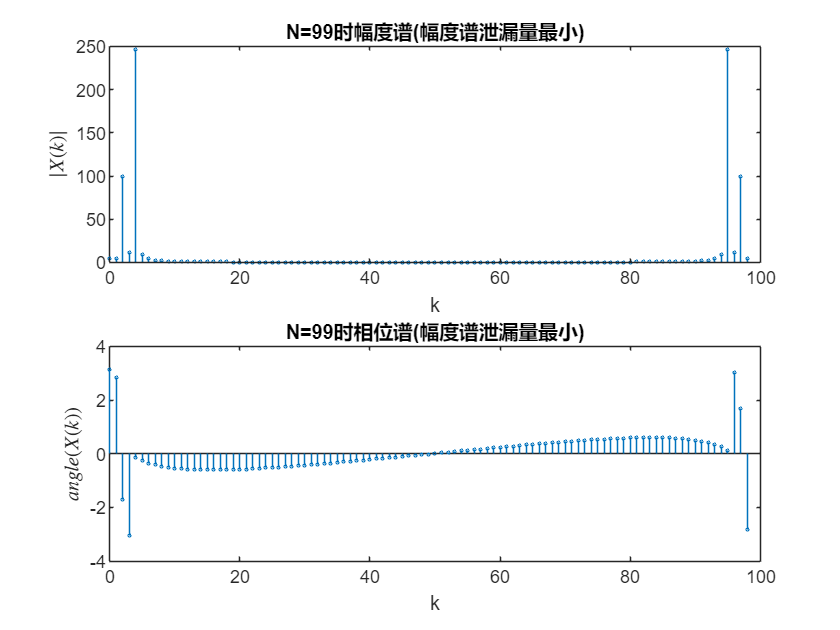


figure 
subplot(2,1,1)
stem(k3,abs(Xk3),MarkerSize=1.5)
title("N=99时幅度谱(幅度谱泄漏量最小)")
xlabel("k")
ylabel("$|X(k)|$","Interpreter","latex")
subplot(2,1,2)
stem(k3,angle(Xk3),MarkerSize=1.5)
title("N=99时相位谱(幅度谱泄漏量最小)")
xlabel("k")
ylabel("$angle(X(k))$","Interpreter","latex")

function [Xk,k] = dft(xn,N)
    n = 0:1:N-1;
    k = 0:1:N-1;
    WN = exp(-1j*2*pi/N);
    nk = n'*k;
    WNnk = WN .^ nk;
    Xk = xn*WNnk;
end